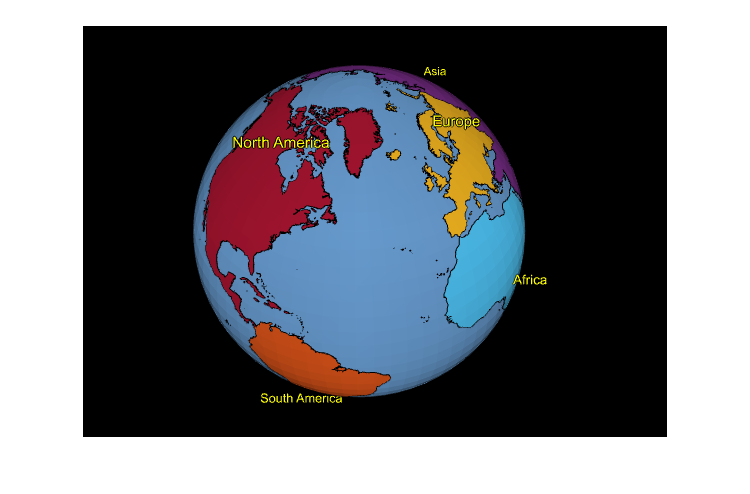

s = jsondecode(fileread('continents.json'));

f = fvclear;

R = 6371;
latlon2geocent = @(latlon) R .* [cosd(latlon(:,1)) .* cosd(latlon(:,2)) cosd(latlon(:,1)) .* sind(latlon(:,2)) sind(latlon(:,1))];

[lat,lon] = ndgrid(-90:5:90,-180:5:180);
ll_earth = [lat(:) lon(:)];
tri_poly = delaunay(ll_earth);
xyz_poly = latlon2geocent(ll_earth);
fvMesh(tri_poly,xyz_poly,[0.4 0.6 0.8],'AutoCalcNormals',false,'DepthOffset',10);

fvhold on

for i=1:numel(s.features)
    name = s.features(i).properties.CONTINENT;

    % extract polygon list
    cont_polygons = s.features(i).geometry.coordinates;
    cont_polygons = cellfun(@(c) fliplr(permute(c,[2 3 1])),cont_polygons,'uni',0);

    % extract edges as multiple lines separated by nan
    poly_edge = cont_polygons';
    poly_edge(2,:) = {[nan nan]};
    poly_edge = vertcat(poly_edge{:});
    xyz_line = latlon2geocent(poly_edge);

    % edges start and end at the same point: remove last point
    P1 = cellfun(@(c) c(1:end-1,:),cont_polygons(:,1),'uni',0);

    % create edges connection (for 4 edge: [1 2 ; 2 3 ; 3 4 ; 4 1])
    nPts = cumsum([0 ; cellfun(@height,P1)]);
    limPts = [nPts(1:end-1)+1 nPts(2:end)];
    C = arrayfun(@(a,b) [(a:b-1)' (a+1:b)' ; b a],limPts(:,1),limPts(:,2),'uni',0);
    C = vertcat(C{:}); % edge connections
    P1 = vertcat(P1{:}); % edges points

    % get non duplicate earth points for interior of polygon
    k = inpolygon(ll_earth(:,1),ll_earth(:,2),poly_edge(:,1),poly_edge(:,2));
    P2 = ll_earth(k,:);

    % triangulate
    P = [P1 ; P2(~ismember(P2,P1,'rows'),:)];
    DT = delaunayTriangulation(P,C);
    tri_poly = DT(isInterior(DT),:);
    xyz_poly = latlon2geocent(DT.Points);


    % Render
    textLoc = latlon2geocent(mean(P,1)) .* 1.1;
    fvLine(f,xyz_line,[0 0 0],'DepthOffset',-10,'Name',[name ' border']);
    fvMesh(f,tri_poly,xyz_poly,'AutoCalcNormals',false,'Name',name);
    fvText(name,'HorizontalAlignment','Center','ConstantSizeCutoff',3*R).Translate(textLoc);

end

f.ResetCamera;
f.Snapshot;